# System Identification

## 1. Data Preparation

### 1.1 Load data from file

data = load("data/Id0.1728.mat").data;
disp(data);

    l_hy: [10220001×3 double]
    t_hy: [10220001×1 double]
       t: [10220001×1 double]
       y: [10220001×3 double]
       u: [10220001×3 double]



l_hy = data.l_hy;
t_hy = data.t_hy;
t = data.t;
y = data.y;
u = data.u;

% figure;
% subplot(3, 1, 1);
% plot(t, u);
% title('Excitation Signal'); xlabel('t'); ylabel('u(t)');
% subplot(3, 1, 2);
% plot(t, y);
% title('Plant Output'); xlabel('t'); ylabel('y(t)');
% subplot(3, 1, 3);
% plot(t_hy, l_hy);
% title('Hydraulic Output'); xlabel('t'); ylabel('h');

### 1.2 Apply differencing

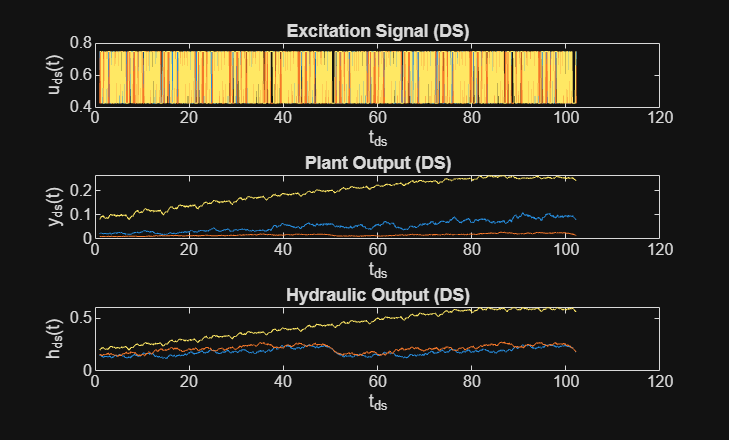

startIdx = find(t >= 1, 1, "first"); % drop the data before 1s

% downsample u, y to a slower rate
N_b = 0.1 / 1e-5; % Ts_ctrl / Ts_local
u_ds = u(startIdx : N_b : end, :);
y_ds = y(startIdx : N_b : end, :);
t_ds = t(startIdx : N_b : end);
l_hy_ds = l_hy(startIdx : N_b : end, :);
t_hy_ds = t_hy(startIdx : N_b : end);

figure;
subplot(3, 1, 1);
plot(t_ds, u_ds);
title('Excitation Signal (DS)'); xlabel('t_{ds}'); ylabel('u_{ds}(t)');
subplot(3, 1, 2);
plot(t_ds, y_ds);
title('Plant Output (DS)'); xlabel('t_{ds}'); ylabel('y_{ds}(t)');
subplot(3, 1, 3);
plot(t_hy_ds, l_hy_ds);
title('Hydraulic Output (DS)'); xlabel('t_{ds}'); ylabel('h_{ds}(t)');


% apply differencing
delta_u = diff(u_ds);
delta_y = diff(y_ds);
fprintf("delta_u: rms=%g, nnz=%d/%d\n", rms(delta_u), nnz(delta_u), numel(delta_u));

delta_u: rms=0.228846, nnz=2.288464e-01/2.270373e-01
delta_u: rms=1516, nnz=3036/

fprintf("delta_y: rms=%g, nnz=%d/%d\n", rms(delta_y), nnz(delta_y), numel(delta_y));

delta_y: rms=0.00279327, nnz=6.245258e-04/2.689362e-03
delta_y: rms=3036, nnz=3036/

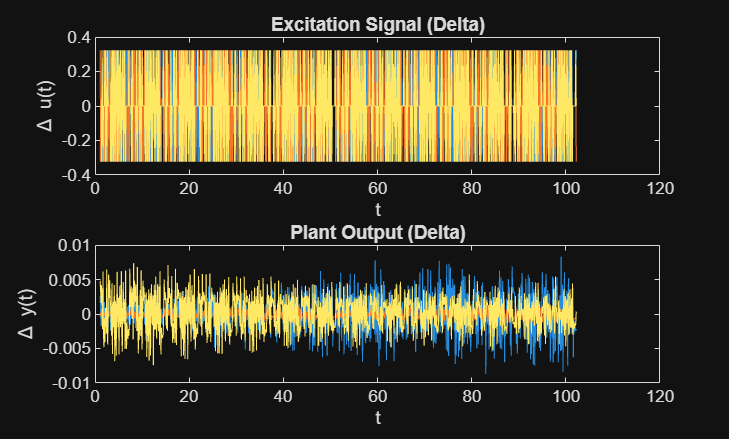


figure;
subplot(2, 1, 1);
plot(t_ds(2 : end), delta_u);
title('Excitation Signal (Delta)'); xlabel('t'); ylabel('\Delta u(t)');
subplot(2, 1, 2);
plot(t_ds(2 : end), delta_y);
title('Plant Output (Delta)'); xlabel('t'); ylabel('\Delta y(t)');

## 2. Choose the model structure

### 2.1 Choose orders $n_a$, $n_b$

n_a = 2;
n_b = 1;

## 3. Write the regression form

Rewrite the CARIMA as: 


$$\Delta y(k)
= -\sum_{i=1}^{n_a} a_i\,\Delta y(k-i)
+ \sum_{j=0}^{n_b} b_j\,\Delta u\!\bigl(k-1-d-j\bigr)
+ e(k)$$


Define: 

- parameter vector


$$\theta = \bigl[\, a_1 \ \cdots \ a_{n_a} \ \ b_0 \ \cdots \ b_{n_b} \,\bigr]^{T}$$


- regression vector


$$\varphi(k)=
\left[
\begin{array}{c}
-\Delta y(k-1) \\
\vdots \\
-\Delta y(k-n_a) \\
\Delta u(k-1-d) \\
\vdots \\
\Delta u(k-1-d-n_b)
\end{array}
\right]
$$


Then


$$\Delta y(k)=\varphi^{T}(k)\,\theta + e(k)$$


## 4. Estimate parameters

Collect data for $k = k_0, \ldots, k_N$, stack: 

$Y =
\left[
\begin{array}{c}
\Delta y(k_0) \\
\vdots \\
\Delta y(k_N)
\end{array}
\right]$, $\Phi =
\left[
\begin{array}{c}
\varphi^{\top}(k_0) \\
\vdots \\
\varphi^{\top}(k_N)
\end{array}
\right]$

Then: 


$$\hat{\theta}
=
\left( \Phi^{\top} \Phi \right)^{-1} \Phi^{\top} Y$$


d = 0;
p = n_a + n_b + 1;
S = zeros(3 * p,3 * p);
rhs = zeros(3 * p,3);

k0 = max(n_a, n_b + d + 1) + 1;
for k = k0 : size(delta_y, 1)
    phi_y = -delta_y(k - 1 : -1 : k - n_a, :).';            % 3 x n_a
    phi_y = phi_y(:);                                       % 1 x (3 * n_a)
    phi_u = delta_u(k - 1 - d : -1 : k - 1 - d - n_b, :).'; % 3 * (n_b + 1)
    phi_u = phi_u(:);                                       % 1 x (3 * (n_b + 1))
    phi = [phi_y; phi_u];                                   % (3 * p) x 1
    S = S + phi * phi';
    rhs = rhs + phi * delta_y(k, :);
end

theta_hat = S \ rhs;

## 5. Model validation

% one-step-ahead validation
Phi = [];
for k = k0 - 1 : -1 : k0 - n_a
    Phi = cat(2, Phi, -delta_y(k : end - (k0 - 1 - k) - 1, :));
end
for k = k0 - 1 : -1 : k0 - 1 - n_b
    Phi = cat(2, Phi, delta_u(k : end - (k0 - 1 - k) - 1, :));
end

y_hat = Phi * theta_hat;
figure;
for i = 1 : 3
    subplot(3, 1, i);
    plot(t_ds(k0+1:end), [delta_y(k0:end, i) y_hat(:, i)]);
end

## 6. GPC

theta_hat = reshape(theta_hat', 3, 3, []);
A = cell(3, 3);
B = cell(3, 3);
for i = 1 : 3
    for j = 1 : 3
        tmp = theta_hat(i, j, 1:n_a);
        A{i, j} = [1 tmp(:).'];
    end
end
for i = 1 : 3
    for j = 1 : 3
        tmp = theta_hat(i, j, n_a+1:n_a+n_b+1);
        B{i, j} = tmp(:).';
    end
end

N1 = 1;
N2 = 5;
Nu = 3;
alpha = 0.5;
lambda = 1e-2;

r_init = 0.08;
r_set = 0.18;
G = gmat(A, B, N1, N2, Nu);
F = fmat(A, B, N1, N2, y_ds(1000), ...
         delta_y(1000:-1:1000-n_a+1), delta_u(1000:-1:1000-n_b));
R = r_init * eye(N2 - N1 + 1, 1);
for i = 2 : numel(R)
    R(i) = alpha * R(i - 1) + (1 - alpha) * r_set;
end

dU_star = (G' * G + lambda * eye(Nu)) \ G' * (R - F);